root_dir = "C:\Users\olive\OneDrive - University of Surrey\individual project\data";
testdate = "8mscatapultlogs";

file_num = 3;
path = root_dir + "/" + testdate + "/*.csv";
file_names = dir(path)

file_names = 14×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


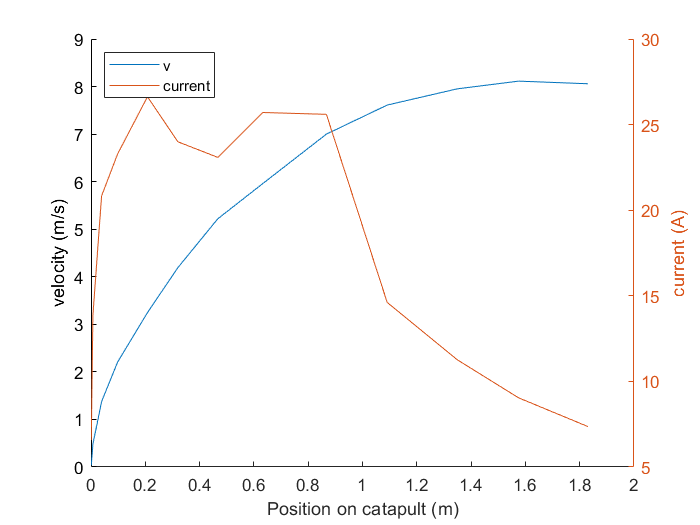

current_file = file_names(file_num);

file = importdata(strcat(current_file.folder, '\', current_file.name), ",");
catapult_data = file.data;
clf
hold on
plot(catapult_data(:,1), catapult_data(:,2))
ylabel("velocity (m/s)")
yyaxis right
ylabel("current (A)")
plot(catapult_data(:,1), abs(catapult_data(:,3)))
%scatter(data(:,1), data(:,4))
legend(["v", "current"], 'Location','northwest' )
hold off
xlabel("Position on catapult (m)")

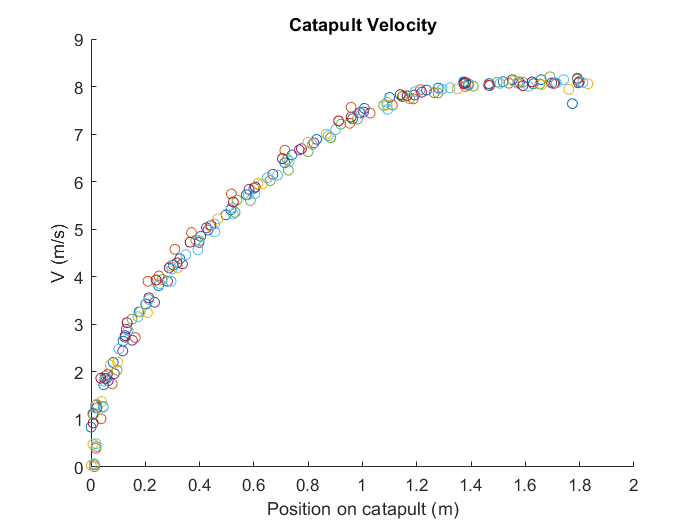

clf
hold on
catapult_new_distance = 0:0.1:2;
for num = 1:14
    file = importdata(file_names(num).folder + "/" + file_names(num).name, ",");
    catapult_data = file.data(file.data(:,1) < 1.84, :);
    new = interp1(catapult_data(2:end,1), catapult_data(2:end,2), catapult_new_distance);
    %scatter(catapult_new_time, new)
    scatter(catapult_data(:,1), catapult_data(:,2))
end
hold off
ylabel("V (m/s)")
xlabel("Position on catapult (m)")
title("Catapult Velocity")
xlim([0,2])

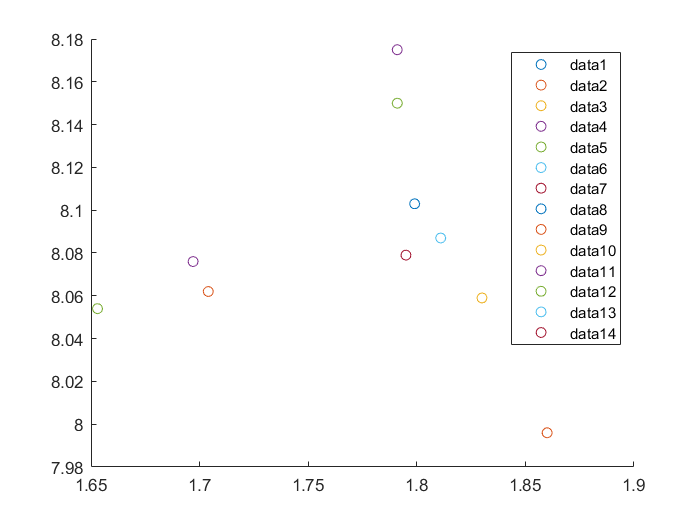

clf
hold on
for num = 1:14
    file = importdata(file_names(num).folder + "/" + file_names(num).name, ",");
    catapult_data = file.data(file.data(:,1) < 2, :);
    scatter(catapult_data(end, 1), catapult_data(end, 2))
end
hold off
legend

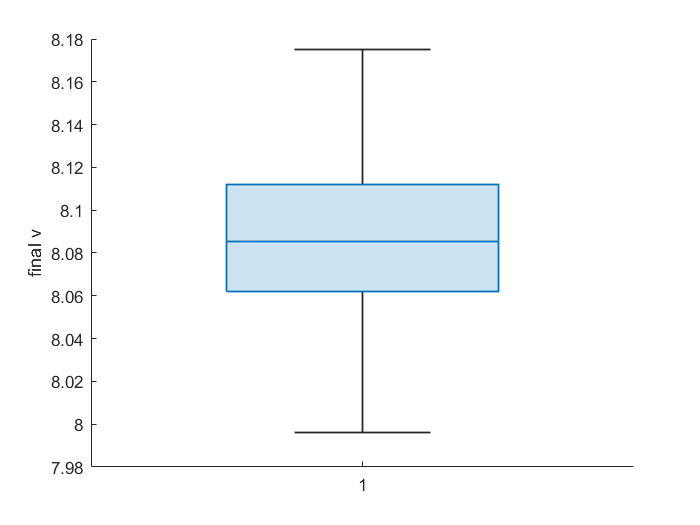

final_v = [];
clf
hold on
catapult_new_distance = 0:0.1:2;
for num = 1:14
    file = importdata(file_names(num).folder + "/" + file_names(num).name, ",");
    catapult_data = file.data(file.data(:,1) < 2, :);
    final_v = [final_v catapult_data(end,2)];
end
boxchart(final_v);
hold off
ylabel("final v")

std(final_v)

ans = 0.0467

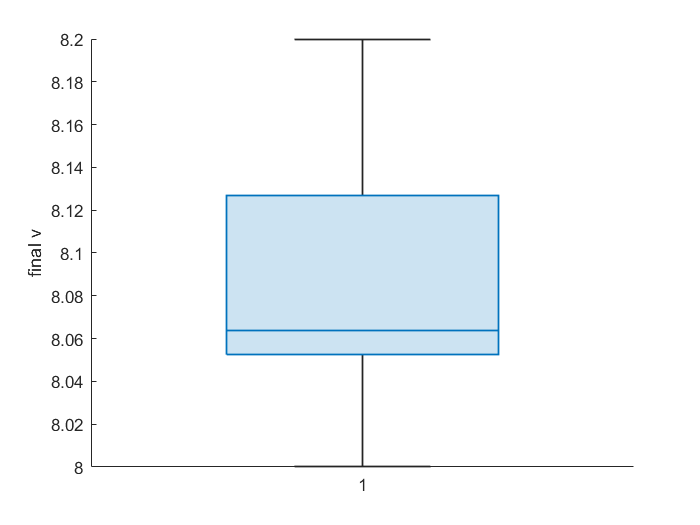

final_v = [];
clf
hold on
catapult_new_distance = 0:0.1:2;
for num = 1:14
    file = importdata(file_names(num).folder + "/" + file_names(num).name, ",");
    catapult_data = file.data(file.data(:,1) < 1.8, :);
    new = interp1(catapult_data(2:end,1), catapult_data(2:end,2), catapult_new_distance);
    new = new(~isnan(new));
    new = new(new>1.75);
    final_v = [final_v new(end)];
end
boxchart(final_v);
hold off
ylabel("final v")

std(final_v)

ans = 0.0506